# Molico (2006) Replication

## Calibration

clear all
close all
clc

tic

mupper=7 %highest value if money holdings on the grid

mupper = 7

N=10000 %number of agents for simulating distribution

N = 10000

iterations=25 %maximum number of iterations for the value function iteration    

iterations = 25

stopping_parameter=0 %the smaller, the more does it iteration take to converge

stopping_parameter = 0

x=0.25

x = 0.2500

alpha=1

alpha = 1

theta=1

theta = 1

beta=0.99 %discount factor

beta = 0.9900

M=1 %Money supply

M = 1

r=1/beta-1 %real interest rate

r = 0.0101

mu_all=[0,0.01,0.1, 0.2] %Money Growth

mu_all =          0    0.0100    0.1000    0.2000


mu_labels={ 'Price Stability','low inflation','midlle inflation' 'high inflation'}

mu_labels = 1×4 cell array
    {'Price Stability'}    {'low inflation'}    {'midlle inflation'}    {'high inflation'}


n_calibration=size(mu_all)

n_calibration =      1     4


n_calibration=n_calibration(1,2)

n_calibration = 4

smoothing_parameter=0.3

smoothing_parameter = 0.3000

correct_dist=1

correct_dist = 1

## Define grid

% sets up a grid where points are located around 50-100 since under the
% most used calibration, many agents were holding money holdings in that
% range
% grids_1=8
% grids_2=8
% grids_3=3
% grids=grids_1+grids_2+grids_3
% 
% m_0=linspace(0,0.80,grids_1)
% m_1=linspace(0.90,2, grids_2)
%  m_2=linspace(2.1,mupper,grids_3);
%  m=[m_0,m_1,m_2]
grids=20

grids = 20

m=linspace(0,mupper ...

m =          0    0.3684    0.7368    1.1053    1.4737    1.8421    2.2105    2.5789    2.9474    3.3158    3.6842    4.0526    4.4211    4.7895    5.1579    5.5263    5.8947    6.2632    6.6316    7.0000


    , grids)


## Options



test_interpolation=0; % checks the interpolation method and displays the initial guess of the value function
test_utility=0; % displays the utility and cost function

display_plot_all=1;
display_plot_V=1;
display_plot_q=1;
display_plot_d=1;
display_plot_meeting=1;
display_plot_Distribution_rough=0;
display_plot_Distribution_smooth=1;
display_plot_cdf=0;
display_plot_money_savings=0;
display_plot_M_Track_1=1;
display_plot_q_all=1;
display_plot_d_all=1;






## set up matrixes

initial_distribution_shock=ones(1,N);
Distribution_number=ones(1,N);
Distribution_0=ones(1,N);
cdf_0=zeros(1,grids);
lamdba_0=zeros(1,grids);
m_savings_1=zeros(1,grids);
m_savings_2=zeros(1,grids);
m_savings_3=zeros(1,grids);

V_all=zeros(grids,n_calibration);
Distribution_all=zeros(N,n_calibration);
q_all=zeros(grids, grids,n_calibration);
d_all=zeros(grids, grids,n_calibration);
price_all=zeros(grids, grids,n_calibration);
f=zeros(100,n_calibration);
xi=zeros(100,n_calibration);
M_track_1=zeros(iterations,n_calibration);

average_price=zeros(1,n_calibration);
std_distribution=zeros(1,n_calibration);
velocity=zeros(1,n_calibration);
average_real_balances=zeros(1,n_calibration);

## Initial Guess

% set an initial guess for the value function
V0=log(1+m)*100  ;

 
% set an initial guess for the pdf distributiuon

for j=1:grids
if m(1,j)>M
lamdba_0(1,j)=1;
break
end
end



M_0=lamdba_0*m';

%ISSUE: the guess was choosen such that that the implied money supply is
%equal to M. But then the pdf does not sum to 1. I don't think this is a
%problem since after 


% compute cdf
for i=1:grids-1
    cdf_0(1,1)=lamdba_0(1,1);
cdf_0(1,i+1)=cdf_0(1,i)+lamdba_0(1,1+i);
end


% Draw from the initial guess
% we draw a random shock [0,1] for each individual in N. Depending on the
% initial guess, the cdf will determine the distributiuon. Notice, the
% distribution_number is determined to determine the grid point which can
% then be used to determine the money holding by using the grid m

found=0; %this parameter indicates whether a certain condition in the loop was satisfied
for i=1:N
initial_distribution_shock(1,i)=unifrnd(0,1); 
for l=1:grids 
   if initial_distribution_shock(1,i)<cdf_0(1,l)
Distribution_number(1,i)=l;
Distribution_0(1,i)=m(1,Distribution_number(1,i));
found=1;
   end
    
if found==1
found=0;
    break
end
       
end

end

 


## Test interpolation: spline, extrapolate


if test_interpolation==1
    n_interp=1000
V_interp=ones(n_interp);
m_interp=linspace(1,mupper,n_interp);
for i=1:n_interp
V_interp=interp1(m,V0,m_interp,'spline',"extrap");
end

%Plot
hold on

plot(m,V0)
plot(m_interp,V_interp)
legend('grids', 'interpolation')

hold off

clear  m_interp n_interp V_interp
end


## Test utility and cost function


if test_utility==1
u=Utility(m)
c=cost_function(m)
s=u-c
figure(1)

hold on
plot(m, u)
plot(m,c)
plot(m,s)
legend('Utility', 'Cost', 'Surplus')
title('Functional Form')
hold off
clear u c s
end

## Iteration

 for calibriation=1:n_calibration
mu=mu_all(1,calibriation);
[V_all(:,calibriation), q_all(:,:,calibriation),d_all(:,:,calibriation),Distribution_all(:,calibriation),...
    lamdba,cdf,M_track_1(:,calibriation), M_track_2,Meeting,i] = Iter_Molico_06(iterations, N,m...
     ,grids,V0,lamdba_0, cdf_0,Distribution_0,M_0,r,alpha,x,mu,theta,mupper, stopping_parameter,correct_dist)

 if cdf(grids)==1
    disp('cdf adds up to one')
else 
    disp('cdf does not add up to one')
    cdf(grids)
 end



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     0.9799    1.2306    1.1053    1.2306    0.9799    1.1053    1.1053    1.1053    1.1053    1.1053    0.9799    1.2306    1.1053    1.1053    1.1053    1.2306    0.9799    0.9799    1.2306    1.1053    1.1053    1.1053    0.9799    1.2306    0.9799    1.2306    1.1053    1.1053    1.2306    0.9799    1.2306    0.9799    1.1053    1.1053    1.2306    0.9799    1.1053    1.1053    1.1053    1.2306    0.9799    0.9799    1.2306    1.1053    1.2306    0.9799    0.9799    1.2306    1.1053    0.9799


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.1168    1.0937    1.1053    1.3573    0.8532    1.1053    0.9814    1.2292    1.1053    1.1053    0.9799    1.2306    0.9814    1.2292    1.2292    1.1067    0.9799    1.1168    1.0937    1.2432    0.9673    1.1053    0.9799    1.1030    1.1076    1.2306    1.1053    1.1053    1.2306    0.9799    1.2306    1.1168    0.9683    1.1053    1.3573    0.8532    1.1053    1.1053    0.9814    1.3545    0.8472    1.1126    1.2306    1.2292    1.1067    0.8575    1.1023    1.1030    1.2329    0.8575


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.1168    1.0937    1.2421    1.2205    0.8532    1.2286    0.8580    1.2292    0.9819    1.2286    0.9799    1.2306    0.9814    1.2292    1.2292    1.1067    0.8471    1.2496    0.9705    1.3664    1.1041    0.9685    0.9799    1.1030    1.1076    1.1040    1.2319    1.2421    1.0938    0.9799    1.2306    1.1168    0.9683    1.1053    1.4872    0.7233    0.9819    1.2286    0.9814    1.4844    0.7174    1.1126    1.2306    1.2292    1.2301    0.7341    1.1023    1.2263    1.1096    0.9942


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.2403    0.9702    1.2421    1.0753    0.9984    1.3668    0.7199    1.2292    0.9819    1.2286    0.8472    1.3633    0.9814    1.0923    1.3660    0.9730    0.9808    1.1120    1.1081    1.3664    1.1041    1.1051    0.8433    1.1030    1.1076    0.9703    1.3655    1.1154    1.2205    0.9799    1.1043    1.2432    0.9683    1.1053    1.6213    0.5892    1.1184    1.0921    0.9814    1.4844    0.7174    0.9890    1.3541    1.2292    1.3486    0.6156    0.9789    1.3497    0.9861    1.1177


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.2403    0.9702    1.1152    1.2022    1.1344    1.2308    0.8517    1.0973    1.1068    1.1038    0.7175    1.4930    1.1176    0.9561    1.3660    0.9730    0.9808    0.9880    1.2321    1.2250    1.2455    0.9812    0.9672    1.2382    0.9724    0.8381    1.4978    1.1154    1.3460    0.8544    1.1043    1.1162    1.0953    0.9629    1.7637    0.5892    1.2537    0.9569    0.9814    1.3382    0.8635    0.9890    1.3541    1.2292    1.3486    0.6156    1.1152    1.2134    0.8537    1.2501


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.3770    0.8336    1.1152    1.0665    1.2701    1.3672    0.7153    1.0973    0.9821    1.2284    0.7175    1.6273    0.9833    0.8247    1.4975    0.9730    1.1065    0.8623    1.2321    1.2250    1.3607    0.8660    0.9672    1.2382    0.8491    0.9613    1.6323    0.9809    1.3460    0.8544    0.9706    1.2499    1.0953    1.0888    1.6377    0.5892    1.2537    0.8254    1.1128    1.4675    0.7343    0.9890    1.3541    1.2292    1.4782    0.4860    1.1152    1.0681    0.9990    1.2501


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.2454    0.9651    0.9931    1.1886    1.3833    1.2539    0.7153    1.0973    0.9821    1.2284    0.7175    1.4784    1.1322    0.8247    1.4975    1.1087    0.9709    0.8623    1.2321    1.0972    1.4884    0.7388    1.0944    1.2382    0.8491    0.8305    1.7631    0.8496    1.4773    0.7201    1.1049    1.3772    0.9680    0.9553    1.7712    0.5892    1.2537    0.9513    0.9869    1.3370    0.8648    0.8576    1.4856    1.2292    1.4782    0.4860    1.2497    0.9336    0.9990    1.2501


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.3557    0.8548    1.1200    1.0617    1.5231    1.1142    0.7153    1.0973    1.1090    1.1015    0.7175    1.4784    1.1322    0.8247    1.4975    0.9748    1.1048    0.8623    1.2321    1.0972    1.3354    0.8918    1.2288    1.1037    0.7173    0.9623    1.9136    0.6990    1.4773    0.7201    0.9838    1.4983    1.0951    0.8283    1.7712    0.5892    1.2537    0.9513    0.9869    1.2060    0.9958    0.7435    1.5997    1.3649    1.3425    0.5754    1.1603    0.9336    0.9990    1.3779


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.2165    0.9940    1.1200    1.1962    1.3886    1.1142    0.6061    1.2065    0.9658    1.2448    0.7175    1.3438    1.2668    0.8247    1.4975    0.9748    1.1048    0.7394    1.3550    0.9637    1.4690    1.0261    1.0945    0.9770    0.8441    0.8336    2.0423    0.5964    1.5799    0.8386    0.8653    1.3632    1.2302    0.7080    1.8916    0.5011    1.3417    1.0984    0.8398    1.2060    0.9958    0.7435    1.5997    1.3649    1.3425    0.4858    1.2499    0.8125    1.1201    1.3779


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.2165    1.1403    0.9738    1.1962    1.2489    1.2539    0.7094    1.1032    0.9658    1.3809    0.5813    1.3438    1.2668    0.9484    1.3738    0.8525    1.2270    0.6306    1.4638    0.9637    1.3276    1.1675    1.0945    0.9770    0.8441    0.7275    2.1485    0.7042    1.4721    0.8386    0.8653    1.2308    1.3625    0.6029    1.9967    0.5011    1.3417    1.2330    0.7053    1.2060    0.9958    0.8803    1.4629    1.3649    1.1939    0.6344    1.2499    0.6961    1.2365    1.3779


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.3188    1.0380    0.8525    1.3174    1.3854    1.1174    0.7094    0.9701    1.0989    1.3809    0.5813    1.4821    1.1285    1.0930    1.2291    0.8525    1.0967    0.7609    1.4638    0.9637    1.3276    1.2161    1.0459    1.1032    0.7178    0.6270    2.2490    0.8171    1.3592    0.8386    0.8653    1.3786    1.2148    0.5154    2.0841    0.4260    1.4168    1.3615    0.5767    1.2060    0.9958    1.0046    1.3386    1.5036    1.0552    0.6344    1.1191    0.8269    1.3651    1.2493


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4485    0.9082    0.7523    1.4177    1.3853    1.1174    0.7094    1.1138    0.9552    1.3809    0.6578    1.4056    1.1285    1.0930    1.3656    0.7161    1.0967    0.8837    1.3411    0.8443    1.4470    1.2161    1.1721    0.9770    0.7178    0.5346    2.3413    0.6993    1.4771    0.7394    0.9644    1.2392    1.3542    0.6055    1.9940    0.3687    1.4742    1.2287    0.7095    1.0610    1.1408    1.1489    1.1942    1.3682    1.1906    0.7161    1.0374    0.9544    1.2376    1.2493


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.3142    1.0426    0.6505    1.5194    1.5248    0.9779    0.8246    0.9985    1.0970    1.2391    0.7601    1.3033    1.1285    1.0930    1.3656    0.7161    1.2226    0.7577    1.3411    0.8443    1.3063    1.3568    1.2689    0.8802    0.7178    0.5346    2.5035    0.5371    1.5770    0.6395    0.8415    1.3621    1.4840    0.4757    2.1481    0.2146    1.5740    1.1288    0.6131    1.1574    1.1408    1.0152    1.3280    1.3682    1.1906    0.8321    0.9214    0.9544    1.2376    1.3970


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4526    0.9041    0.5646    1.6053    1.5248    0.9779    0.8246    0.8956    1.1999    1.2391    0.7601    1.1718    1.2600    1.1864    1.2722    0.8220    1.1166    0.7577    1.3410    0.7346    1.4160    1.3567    1.2688    0.8802    0.7178    0.6232    2.4149    0.4672    1.6468    0.6395    0.7364    1.4671    1.3337    0.6259    2.1481    0.1938    1.5948    0.9889    0.7531    1.1574    1.1407    1.1075    1.2356    1.2203    1.3384    0.7237    1.0297    0.9544    1.2375    1.5266


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4526    0.9041    0.6491    1.5207    1.5247    0.8573    0.9451    0.8955    1.0579    1.3811    0.8940    1.0378    1.2599    1.3323    1.1262    0.8220    1.1166    0.7577    1.3410    0.7345    1.4159    1.4960    1.1295    0.8802    0.7954    0.5456    2.4148    0.4072    1.7068    0.6395    0.8498    1.3536    1.4613    0.4982    2.1480    0.1737    1.6148    0.8609    0.8810    1.1573    1.0153    1.2329    1.0999    1.3559    1.3383    0.8357    0.9176    0.9544    1.2375    1.6690


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4525    0.9040    0.6821    1.4877    1.3739    1.0081    0.9451    1.0094    0.9439    1.3810    0.8049    1.1268    1.1241    1.4680    1.1262    0.9022    1.0363    0.7576    1.2099    0.8656    1.5435    1.3684    1.2520    0.7576    0.6959    0.6450    2.2540    0.5679    1.8393    0.5069    0.7391    1.4643    1.6025    0.3570    2.2897    0.0319    1.4699    1.0057    0.8809    1.1573    1.0152    1.2746    1.0582    1.2245    1.4697    0.7316    1.0217    0.9544    1.2374    1.5304


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0


Distribution_new =     1.4525    0.9040    0.6821    1.5777    1.2837    0.8827    1.0704    1.0094    0.9439    1.3810    0.8048    1.0054    1.2454    1.6093    0.9848    0.9022    0.9408    0.8530    1.0769    0.9984    1.5434    1.2376    1.3827    0.6609    0.7925    0.7340    2.1648    0.5678    1.8392    0.5069    0.7390    1.4642    1.6024    0.3570    2.3887         0    1.5968    0.8787    1.0027    1.0354    1.0152    1.2745    0.9345    1.3480    1.4696    0.7315    0.9075    1.0685    1.2374    1.5304


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0


Distribution_new =     1.5933    0.7630    0.7477    1.5120    1.2836    0.7730    1.1800    1.0093    0.9438    1.3809    0.8048    1.0054    1.2453    1.7367    0.8572    0.8011    1.0419    0.7513    1.1785    1.1122    1.4294    1.2375    1.3826    0.6609    0.6938    0.8326    2.3027    0.4298    1.6884    0.6576    0.6472    1.5559    1.4668    0.4925    2.4322         0    1.4879    0.9875    1.0836    0.9545    0.8970    1.3926    0.9345    1.4714    1.3460    0.7315    1.0293    0.9466    1.2373    1.6823


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0


Distribution_new =     1.4488    0.9073    0.6605    1.5990    1.2836    0.7729    1.1799    0.8936    1.0594    1.5408    0.6447    1.0053    1.2453    1.7768    0.8169    0.8010    1.0418    0.7512    1.1784    1.1121    1.4294    1.2374    1.3825    0.6609    0.7243    0.8020    2.3025    0.4298    1.6883    0.5816    0.7231    1.5558    1.5904    0.3688    2.6057         0    1.3561    1.1191    1.0835    0.8440    1.0073    1.2469    1.0801    1.4713    1.2185    0.8589    1.0292    0.9465    1.2372    1.6821


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0


Distribution_new =     1.3088    1.0472    0.6605    1.5989    1.2835    0.8789    1.0738    0.8935    0.9495    1.6506    0.5694    1.0806    1.1491    1.8729    0.7236    0.8943    0.9333    0.8597    1.1784    1.1121    1.5505    1.1161    1.3275    0.7159    0.8132    0.7130    2.3024    0.4932    1.6248    0.5816    0.6461    1.6328    1.7333    0.2258    2.4448    0.1608    1.4943    0.9807    1.0835    0.9568    0.8944    1.3280    0.9989    1.4712    1.2184    0.9806    0.9074    0.9465    1.3545    1.5647


Value function has not converged


i = 20


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1054         0         0         0         0


Distribution_new =     1.3087    1.0471    0.7404    1.5189    1.3997    0.7625    1.0737    0.8935    0.8716    1.7283    0.5694    1.0805    1.1490    2.0317    0.5646    0.9637    0.8637    0.9879    1.0500    1.2410    1.4214    1.1160    1.4846    0.5586    0.7223    0.8038    2.1859    0.6095    1.6246    0.6629    0.5647    1.7552    1.6106    0.2627    2.4076    0.1940    1.4610    0.9807    1.0834    0.8400    1.0110    1.3279    0.9988    1.4711    1.2183    0.8799    1.0081    0.8488    1.4520    1.5646


Value function has not converged


i = 21


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1054         0         0         0


Distribution_new =     1.3086    0.9339    0.8535    1.5187    1.3996    0.7624    0.9678    0.9992    0.7836    1.8160    0.5693    0.9970    1.2322    2.0315    0.5645    0.9636    0.8636    0.9878    0.9312    1.3596    1.4213    1.2246    1.3757    0.5585    0.8056    0.7203    2.1857    0.6095    1.6245    0.7524    0.4751    1.6206    1.7449    0.3014    2.3687    0.1754    1.4794    0.9806    0.9669    0.9563    1.1325    1.2062    0.9987    1.4710    1.2182    0.8798    1.1117    0.7450    1.2981    1.7183


Value function has not converged


i = 22


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1054         0         0


Distribution_new =     1.3085    0.9338    0.9607    1.4113    1.2770    0.8848    0.9677    0.9992    0.7835    1.8159    0.5693    0.9969    1.3426    1.9209    0.5040    1.0240    0.8635    1.1057    0.8131    1.4734    1.3073    1.2245    1.2824    0.6517    0.9085    0.6174    2.3388    0.4561    1.7431    0.6335    0.5446    1.5509    1.6435    0.4026    2.4990    0.0449    1.4793    0.8849    1.0624    0.9563    1.1324    1.3466    0.8582    1.6096    1.0794    0.8797    1.1116    0.7450    1.4317    1.5844


Value function has not converged


i = 23


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1054         0


Distribution_new = 1×10000
    1.4188    0.8233    0.9606    1.4111    1.2769    0.8003    1.0520    0.9991    0.7835    1.8157    0.6332    0.9328    1.3424    1.7852    0.6394    0.9117    0.9756    1.1056    0.7778    1.5085    1.4399    1.0917    1.2823    0.6516    0.9084    0.5595    2.3964    0.5177    1.6813    0.7158


Value function has not converged


i = 24


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1054


Distribution_new = 1×10000
    1.5537    0.6881    0.9605    1.4110    1.2768    0.8826    0.9695    1.0943    0.6880    1.9727    0.4760    1.0242    1.2508    1.7850    0.6394    0.9732    0.9139    1.1055    0.7777    1.3854    1.5626    1.1916    1.1821    0.5919    0.9679    0.5042    2.4514    0.5177    1.8224    0.5744


Value function has not converged


i = 25

V_all = 20×4
    0.0002         0         0         0
  253.6137         0         0         0
  332.6899         0         0         0
  361.6405         0         0         0
  380.0430         0         0         0
  395.2859         0         0         0
  408.7464         0         0         0
  420.6030         0         0         0
  431.1145         0         0         0
  440.5576         0         0         0


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9140    0.8564    0.7344    0.6461    0.6020    0.5778    0.5534    0.5278    0.5039    0.4818    0.4608    0.4414    0.4215    0.4074    0.3789    0.3967    0.3682    0.3225    0.3167    0.0000
    0.9531    0.9195    0.8466    0.7927    0.7659    0.7502    0.7337    0.7164    0.7001    0.6849    0.6701    0.6565    0.6420    0.6322    0.6101    0.6289    0.5962    0.5698    0.5646    0.0000
    0.9656    0.9403    0.8864    0.8479    0.8295    0.8181    0.8058    0.7931    0.7811    0.7698    0.7588    0.7486    0.7378    0.7302    0.7141    0.7301    0.6980    0.6835    0.6788    0.0000
    0.9700    0.9478    0.9014    0.8696    0.8549    0.8454    0.8351    0.8246    0.8147    0.8053    0.7963    0.7878    0.7789    0.7723    0.7604    0.7731    0.7430  

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0102    0.0159    0.0261    0.0319    0.0344    0.0355    0.0364    0.0372    0.0379    0.0383    0.0387    0.0389    0.0390    0.0390    0.0387    0.0395    0.0382    0.0378    0.0376         0
    0.0197    0.0312    0.0534    0.0680    0.0750    0.0784    0.0815    0.0847    0.0876    0.0902    0.0925    0.0946    0.0965    0.0980    0.1002    0.1003    0.0995    0.1053    0.1056         0
    0.0274    0.0439    0.0773    0.1007    0.1123    0.1181    0.1237    0.1295    0.1349    0.1397    0.1442    0.1482    0.1523    0.1551    0.1611    0.1588    0.1597    0.1720    0.1726         0
    0.0317    0.0513    0.0919    0.1216    0.1367    0.1443    0.1517    0.1596    0.1669    0.1735    0.1798    0.1855    0.1915    0.1952    0.2052    0.1996    0.2031  

Distribution_all = 10000×4
    1.5537         0         0         0
    0.6881         0         0         0
    0.9605         0         0         0
    1.4110         0         0         0
    1.2768         0         0         0
    0.8826         0         0         0
    0.9695         0         0         0
    1.0943         0         0         0
    0.6880         0         0         0
    1.9727         0         0         0


lamdba = 1×20
    0.0027    0.0444    0.1685    0.3000    0.2712    0.1535    0.0483    0.0100    0.0014         0         0         0         0         0         0         0         0         0         0         0


cdf = 1×20
    0.0027    0.0471    0.2156    0.5156    0.7868    0.9403    0.9886    0.9986    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 = 25×4
    1.2277         0         0         0
    1.2623         0         0         0
    1.2751         0         0         0
    1.2833         0         0         0
    1.2862         0         0         0
    1.2862         0         0         0
    1.2877         0         0         0
    1.2873         0         0         0
    1.2874         0         0         0
    1.2871         0         0         0


M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053


Meeting = 1×10000
     5     5     5     5     6     4     6     4     4     6     4     4     4     3     4     3     4     6     4     4     5     4     3     4     7     5     5     4     5     5


i = 0

cdf adds up to one



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.9787    1.2319    1.1053    1.1053    0.9787    1.2319    1.1053    1.2319    0.9787    0.9787    1.2319    1.1053    1.2319    0.9787    1.1053    0.9787    1.2319    0.9787    1.2319    0.9787    1.2319    1.1053    0.9787    1.2319    0.9787    1.2319    1.1053    1.1053    1.1053    1.1053


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.1052    1.1053    1.2315    0.9790    0.9798    1.2307    0.9790    1.3570    1.1052    0.8544    1.2307    1.1053    1.0898    1.1207    1.1053    0.8446    1.3660    1.1191    1.0915    0.8549    1.3557    1.2455    0.8396    1.2307    1.1052    1.1053    1.2315    0.9790    1.2315    0.9790


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.2455    0.9651    1.2304    0.9801    0.9809    1.2296    0.9801    1.2196    1.2404    0.9838    1.1025    1.1053    0.9527    1.2578    1.2455    0.7067    1.2167    1.2658    1.2317    0.7170    1.3534    1.1137    0.9725    1.2296    1.1052    1.1053    1.2304    0.9801    1.2304    1.1071


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3748    0.8357    1.2293    0.9813    0.9820    1.2285    1.1226    1.0772    1.2392    1.1083    0.9791    0.9771    1.0822    1.2565    1.2442    0.5814    1.3446    1.2644    1.0890    0.8620    1.3512    0.9854    1.1019    1.0977    1.2361    1.2457    1.0888    0.9813    1.2293    0.9789


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3724    0.9703    1.0960    0.8433    1.1222    1.2274    1.1224    1.2075    1.1080    1.1082    0.8506    1.1079    1.0824    1.1120    1.3861    0.5861    1.3425    1.2630    1.0892    0.7357    1.4775    0.9865    0.9721    1.2276    1.0924    1.3870    1.0890    0.8528    1.3578    0.8411


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3700    0.9715    0.9642    0.9776    1.1220    1.2263    1.1223    1.0636    1.2509    1.2402    0.7209    1.2495    0.9409    0.9799    1.5156    0.7151    1.2159    1.1172    1.2337    0.6167    1.5964    0.9875    0.9733    1.3498    0.9692    1.2362    1.2374    0.7261    1.4845    0.9781


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3676    0.9727    0.9655    0.9787    1.2560    1.0910    1.1221    0.9220    1.3916    1.1025    0.8608    1.2482    1.0790    0.8444    1.5119    0.7186    1.2150    1.2386    1.1110    0.7491    1.4641    0.9886    1.1106    1.2115    0.9704    1.2350    1.2362    0.7295    1.4811    0.8464


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.2161    1.1230    0.9667    0.9798    1.4000    0.9458    0.9776    1.0680    1.5382    0.9534    0.8630    1.2469    1.0792    0.8468    1.5083    0.5983    1.3378    1.0988    1.2496    0.8868    1.3263    0.9896    1.1105    1.3675    0.8146    1.2339    1.2350    0.6131    1.5974    0.8488


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.2151    1.1229    0.9680    0.9810    1.5197    0.8249    1.1187    0.9284    1.5343    1.0949    0.7250    1.2457    1.0795    0.8491    1.5047    0.4987    1.4398    0.9441    1.4030    0.9490    1.2640    0.9907    0.9650    1.5107    0.8172    1.2327    1.2338    0.6175    1.5930    0.9976


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.2141    1.1227    0.9692    0.9821    1.6707    0.6727    1.2589    0.7897    1.7103    0.9151    0.8613    1.1115    0.9166    1.0145    1.3469    0.6583    1.4368    1.0869    1.2590    1.0984    1.1146    0.8551    1.1028    1.5070    0.8198    1.2316    1.3805    0.4741    1.5886    0.9985


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3556    0.9801    0.9704    0.9832    1.8180    0.5242    1.1123    0.9377    1.8582    0.7635    0.8635    1.1114    0.7856    1.1480    1.1921    0.8149    1.2799    1.2411    1.1063    1.2497    0.9667    1.0052    1.1028    1.3481    0.9777    1.0796    1.5288    0.4798    1.5843    0.9995


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3534    0.9812    0.8307    1.1252    1.6520    0.6890    1.2623    0.7891    1.8514    0.9175    0.7147    1.1114    0.9413    0.9948    1.1913    0.6905    1.4053    1.2398    1.2491    1.1056    0.8198    1.1542    1.1028    1.1918    1.1330    1.0799    1.5250    0.4105    1.6548    0.8499


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1042         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3511    0.9823    0.8331    1.2684    1.5036    0.6927    1.4144    0.6383    1.8447    1.0302    0.6072    1.1113    0.8094    1.1291    1.1905    0.6942    1.5587    1.0825    1.2478    1.2572    0.6707    1.2975    0.9590    1.3435    0.9801    0.9248    1.6764    0.4167    1.8115    0.6905


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3488    0.9834    0.8869    1.2156    1.6495    0.5469    1.4116    0.6425    1.8380    0.8865    0.7559    1.1112    0.8120    0.9786    1.3399    0.6978    1.5546    1.0826    1.0919    1.4104    0.6746    1.1459    1.1101    1.3413    0.8593    1.0483    1.6712    0.3616    1.8663    0.8328


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3465    0.9844    1.0259    1.0774    1.6445    0.5518    1.4087    0.6466    1.8313    0.7762    0.8712    1.2541    0.6715    0.8401    1.4772    0.5948    1.6571    1.0123    1.1624    1.4075    0.5785    1.2455    1.2641    1.1850    1.0072    0.9029    1.6660    0.3140    1.9137    0.9693


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.3443    0.8687    1.1432    1.0775    1.4735    0.7228    1.2291    0.8275    1.9388    0.6650    0.8732    1.2527    0.6753    0.7141    1.6022    0.5993    1.4933    1.1718    1.1618    1.2368    0.7510    1.0884    1.4183    1.1842    1.0080    0.9047    1.7733    0.2086    1.9063    0.9705


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.5031    0.7098    1.1428    1.0777    1.4701    0.7262    1.2279    0.8299    1.9312    0.7814    0.7627    1.3955    0.5349    0.7175    1.4394    0.7620    1.6380    1.0228    1.1612    1.0876    0.9021    0.9682    1.5356    1.1834    1.0088    0.9064    1.7672    0.2748    1.8409    1.1221


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.4994    0.7133    1.1424    1.1271    1.4175    0.8660    1.0903    0.8323    1.9237    0.6710    0.8790    1.3928    0.5400    0.8563    1.3011    0.7651    1.6332    1.0235    1.1607    1.0877    1.0577    0.8156    1.5317    1.1827    1.1460    0.7718    1.5892    0.4541    1.6964    1.2597


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043         0         0         0         0         0         0


Distribution_new = 1×10000
    1.4958    0.6328    1.2260    0.9877    1.5538    0.7457    1.2128    0.8348    2.0901    0.5010    0.7571    1.5141    0.4811    0.9224    1.4800    0.5873    1.6284    1.0241    1.3173    0.9306    1.2113    0.6649    1.5278    1.1819    1.1456    0.6700    1.6896    0.4599    1.8705    1.0788


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043         0         0         0         0         0


Distribution_new = 1×10000
    1.4922    0.6370    1.1056    1.1079    1.6962    0.6024    1.2117    0.9590    1.9593    0.5064    0.7602    1.5103    0.4867    0.8651    1.5355    0.5919    1.6236    1.1847    1.1554    0.9321    1.3690    0.5101    1.5239    1.0402    1.2861    0.7130    1.6451    0.5429    1.7863    0.9361


Value function has not converged


i = 20


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1044         0         0         0         0


Distribution_new = 1×10000
    1.4886    0.6411    1.2592    0.9540    1.5097    0.7879    1.3793    0.7915    1.9514    0.5117    0.7632    1.5065    0.4250    0.9342    1.5314    0.6899    1.5253    1.2821    1.0566    0.8153    1.4847    0.4428    1.5926    1.0407    1.4653    0.5354    1.4677    0.7203    1.7799    0.8102


Value function has not converged


i = 21


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043         0         0         0


Distribution_new = 1×10000
    1.3036    0.8266    1.2577    0.9553    1.5059    0.7907    1.3767    0.7095    2.0284    0.5779    0.7053    1.5028    0.4311    0.9357    1.3586    0.8624    1.5214    1.2804    1.0570    0.7310    1.5681    0.5349    1.5018    0.8941    1.6090    0.5405    1.4644    0.6766    1.8208    0.8968


Value function has not converged


i = 22


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043         0         0


Distribution_new = 1×10000
    1.1454    0.9854    1.2562    1.1264    1.3323    0.6824    1.4851    0.7130    2.0199    0.5825    0.7088    1.4991    0.3834    0.9908    1.3562    0.8645    1.5175    1.4142    0.9218    0.7343    1.3934    0.7103    1.5987    0.7953    1.4324    0.7174    1.4610    0.8032    1.6913    0.8073


Value function has not converged


i = 23


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1044         0


Distribution_new = 1×10000
    1.1449    0.9863    1.1171    1.2635    1.3301    0.6860    1.6474    0.5505    1.8783    0.7203    0.7122    1.4953    0.4610    0.9205    1.3537    0.7617    1.6184    1.4112    1.0614    0.5994    1.5769    0.5274    1.4227    0.9693    1.4292    0.7208    1.2927    0.9706    1.8565    0.6391


Value function has not converged


i = 24


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1043


Distribution_new = 1×10000
    1.0033    1.1283    1.1609    1.2179    1.4871    0.5306    1.6423    0.4827    1.9439    0.6509    0.7884    1.4916    0.4668    0.8331    1.4402    0.7647    1.6616    1.3603    0.9282    0.7374    1.4025    0.7025    1.4197    0.8577    1.5389    0.6514    1.3637    1.0895    1.7318    0.7498


Value function has not converged


i = 25

V_all = 20×4
    0.0002  110.9112         0         0
  253.6137  284.7101         0         0
  332.6899  338.6798         0         0
  361.6405  360.6146         0         0
  380.0430  375.6216         0         0
  395.2859  388.1679         0         0
  408.7464  399.4901         0         0
  420.6030  409.7636         0         0
  431.1145  419.0508         0         0
  440.5576  427.4919         0         0


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9140    0.8564    0.7344    0.6461    0.6020    0.5778    0.5534    0.5278    0.5039    0.4818    0.4608    0.4414    0.4215    0.4074    0.3789    0.3967    0.3682    0.3225    0.3167    0.0000
    0.9531    0.9195    0.8466    0.7927    0.7659    0.7502    0.7337    0.7164    0.7001    0.6849    0.6701    0.6565    0.6420    0.6322    0.6101    0.6289    0.5962    0.5698    0.5646    0.0000
    0.9656    0.9403    0.8864    0.8479    0.8295    0.8181    0.8058    0.7931    0.7811    0.7698    0.7588    0.7486    0.7378    0.7302    0.7141    0.7301    0.6980    0.6835    0.6788    0.0000
    0.9700    0.9478    0.9014    0.8696    0.8549    0.8454    0.8351    0.8246    0.8147    0.8053    0.7963    0.7878    0.7789    0.7723    0.7604    0.7731    0.7430  

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0102    0.0159    0.0261    0.0319    0.0344    0.0355    0.0364    0.0372    0.0379    0.0383    0.0387    0.0389    0.0390    0.0390    0.0387    0.0395    0.0382    0.0378    0.0376         0
    0.0197    0.0312    0.0534    0.0680    0.0750    0.0784    0.0815    0.0847    0.0876    0.0902    0.0925    0.0946    0.0965    0.0980    0.1002    0.1003    0.0995    0.1053    0.1056         0
    0.0274    0.0439    0.0773    0.1007    0.1123    0.1181    0.1237    0.1295    0.1349    0.1397    0.1442    0.1482    0.1523    0.1551    0.1611    0.1588    0.1597    0.1720    0.1726         0
    0.0317    0.0513    0.0919    0.1216    0.1367    0.1443    0.1517    0.1596    0.1669    0.1735    0.1798    0.1855    0.1915    0.1952    0.2052    0.1996    0.2031  

Distribution_all = 10000×4
    1.5537    1.0033         0         0
    0.6881    1.1283         0         0
    0.9605    1.1609         0         0
    1.4110    1.2179         0         0
    1.2768    1.4871         0         0
    0.8826    0.5306         0         0
    0.9695    1.6423         0         0
    1.0943    0.4827         0         0
    0.6880    1.9439         0         0
    1.9727    0.6509         0         0


lamdba = 1×20
    0.0018    0.0451    0.1756    0.2937    0.2721    0.1454    0.0558    0.0096    0.0009         0         0         0         0         0         0         0         0         0         0         0


cdf = 1×20
    0.0018    0.0469    0.2225    0.5162    0.7883    0.9337    0.9895    0.9991    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 = 25×4
    1.2277    1.2283         0         0
    1.2623    1.2612         0         0
    1.2751    1.2797         0         0
    1.2833    1.2881         0         0
    1.2862    1.2883         0         0
    1.2862    1.2870         0         0
    1.2877    1.2888         0         0
    1.2873    1.2899         0         0
    1.2874    1.2906         0         0
    1.2871    1.2894         0         0


M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053


Meeting = 1×10000
     5     5     2     8     5     5     4     5     3     3     3     6     4     3     5     7     2     6     5     3     5     6     4     4     5     3     5     4     5     5


i = 0.0100

cdf adds up to one



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.0957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.1053    0.9676    1.2430    1.2430    0.9676    1.2430    0.9676    1.1053    0.9676    1.2430    1.1053    1.2430    0.9676    1.1053    1.1053    1.1053    1.1053    0.9676    1.2430    1.1053    1.2430    0.9676    1.2430    0.9676    0.9676    1.2430    1.2430    0.9676    0.9676    1.2430


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.0957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.1053    1.1400    1.0705    1.0683    1.1423    1.2315    1.1273    0.9569    0.9790    1.0683    1.2685    1.3965    0.8140    1.1053    1.1053    1.1053    1.1053    0.9790    1.2315    1.2668    1.0700    1.1400    1.0705    0.9790    0.8188    1.3917    1.2315    0.9790    1.1400    1.0705


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.0957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.1053    1.3111    0.8994    1.2451    0.9655    1.2211    1.1255    0.9692    1.1642    0.8966    1.0898    1.5375    0.8382    1.1053    1.1053    1.1053    1.1053    0.8131    1.3974    1.4309    0.8955    1.1371    1.0734    1.1530    0.6790    1.5390    1.0500    0.8131    1.3135    0.9106


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.0957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.1053    1.2941    1.1094    1.0406    0.9771    1.3922    0.9431    1.1712    0.9687    0.9139    1.2706    1.3222    0.8603    1.1053    1.2846    0.9259    1.1053    0.8373    1.3732    1.4038    0.9129    0.9436    1.2670    1.1491    0.7144    1.5030    1.0546    0.8373    1.1029    1.1201


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.0957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.1053    1.4977    0.8897    1.0459    0.9877    1.3684    0.9566    1.1657    0.7759    1.1338    1.4621    1.0990    0.8806    0.8936    1.4814    1.1651    0.8810    1.0740    1.1366    1.1668    1.1411    1.1672    1.0433    1.3453    0.5470    1.2455    1.2833    0.8596    1.3035    0.9184


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.0957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.1053    1.6975    0.6752    1.0509    0.7696    1.5744    0.9689    1.1607    1.0416    0.8931    1.6634    0.8686    0.8993    0.6672    1.6942    0.9247    1.1350    1.0766    0.8980    1.3977    0.9124    1.3878    0.7997    1.5741    0.4123    1.4148    1.2685    0.8800    1.2870    0.9339


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.8472    1.9065    0.7109    1.3176    0.5353    1.5355    0.7182    1.4181    1.2971    0.6605    1.8755    0.6299    1.1934    0.4265    1.6453    0.9397    1.1325    1.3362    0.6579    1.1255    1.1764    1.0970    1.0924    1.5352    0.4698    1.3891    1.2550    0.6346    1.5359    0.9482


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.0141    1.6944    0.7436    1.5402    0.3423    1.7800    0.4700    1.6751    0.9981    0.4751    2.0338    0.4532    1.4021    0.4828    1.3154    1.2384    1.1303    1.0111    1.0010    1.1238    1.4624    0.8056    1.3750    1.2180    0.3540    1.5341    1.2426    0.9746    1.1993    0.9612


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.6836    1.9833    1.0366    1.2409    0.4056    1.7239    0.7899    1.3605    1.0069    0.5273    1.6383    0.8255    1.3774    0.5344    1.2979    1.3681    0.9872    1.0188    0.6852    1.4464    1.1230    1.1401    1.6889    0.8720    0.4163    1.4984    1.2310    0.6663    1.5104    1.2330


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0960         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.7184    1.9099    1.0420    1.5663    0.1265    2.0160    0.4719    1.3389    0.6541    0.9358    1.5936    0.5503    1.6526    0.3835    1.4796    1.3459    0.9967    0.6606    1.0850    1.4177    1.4604    0.7977    1.6400    1.2887    0.0758    1.1171    1.5685    0.4635    1.7153    1.5967


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0966         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.7499    1.8417    0.6528    1.9205    0.3549    1.7915    0.5241    1.3185    0.6910    0.5905    1.9104    0.9137    1.2881    0.4430    1.4474    0.9323    1.3975    0.4536    1.3291    1.3907    1.4298    0.8225    1.5944    1.6765         0    1.1152    1.1601    0.8851    1.4185    1.7996


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0969         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.4977    2.0596    0.9552    1.5853    0.6775    1.4720    0.8927    0.9783    0.4674    0.8898    2.2664    0.5039    1.2715    0.4974    1.4175    0.9457    1.6518    0.2272    1.7136    0.9611    1.8268    0.4196    1.2909    1.8886    0.2408    0.9640    1.1543    0.9024    1.3910    2.1450


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0977         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.3420    2.1819    1.2478    1.2608    0.7117    1.4390    0.5482    1.3476    0.3237    1.1017    1.7012    1.0178    1.2555    0.5469    1.6763    0.6701    2.0775         0    2.0920    0.5395    1.9286    0.3109    1.2732    2.2517         0    1.4342    0.6880    0.5585    1.7239    2.3430


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0982         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.6500    1.8423    1.2332    1.7555    0.2323    1.8547    0.1465    1.6144    0.0978    1.5365    1.2111    1.0228    1.2402    0.9279    1.2892    0.7046    1.4711    0.6128    2.0056    0.3617    2.0795    0.3760    0.7964    2.6118    0.0915    1.8539    0.2709    0.9496    1.3218    2.7484


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0992         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.6856    1.7755    1.6631    1.2518    0.3038    1.7869    0.4389    1.3537    0.3786    1.2982    1.1985    1.0263    1.2252    0.9397    1.2699    0.7355    0.9733    1.1145    1.5815    0.7654    1.9924    0.4351    0.8194    1.9012    0.7529    1.2722    0.8529    0.9595    1.2997    3.1486


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0993         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.4323    2.0001    1.6116    0.7668    0.8379    2.1866    0.0306    1.7935         0    1.2781    1.1869    1.0295    0.8120    1.3495    1.8335    0.1824    0.9810    1.5597    1.0874    1.1912    1.5123    0.4891    0.8404    1.8292    1.2458    0.7880    0.8710    0.9684    1.2794    2.3346


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1001         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.4862    1.9182    1.5633    0.4769    1.1714    2.0885    0.3407    1.5081    0.0913    1.7993    0.6348    1.4635    0.4012    1.3239    1.7659    0.2579    0.6282    1.8750    1.0845    0.7124    1.9395    0.5381    0.5097    2.1113    1.2292    0.8111    1.3011    0.5616    1.2599    1.5943


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0996         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.3120    2.0678    1.5198    0.5272    1.1617    1.9998    0.4027    1.0757    0.5686    1.2882    1.1187    1.0389    0.8478    1.3012    1.7051    0.7029    0.2895    1.8047    1.0824    0.7424    1.8637    0.3379    0.8023    2.0206    1.6735    0.3736    1.2803    0.6046    1.2426    1.7282


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0998         0         0         0         0         0         0


Distribution_new = 1×10000
    0.3764    1.9805    1.4799    0.5730    1.1528    2.4297         0    1.0742    1.0290    0.8501    1.2777    0.8763    0.8659    0.7686    2.1607    0.7336    0.3559    2.4071    0.4134    0.4645    2.0992    0.5998    0.6246    1.3550    2.2028    0.2519    1.4419    0.8972    0.9732    1.6703


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1007         0         0         0         0         0


Distribution_new = 1×10000
    0.8261    1.5082    1.4423    0.6144    1.1436    2.7969         0    1.0719    1.0307    0.5137    1.6113    0.8913    1.2854    0.3893    2.0638    0.7610    0.4162    2.2887    0.4687    0.5153    2.0076    0.4062    0.8941    0.9446    2.4859    0.3212    1.4076    0.5552    1.3349    1.6161


Value function has not converged


i = 20


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1007         0         0         0         0


Distribution_new = 1×10000
    0.8454    1.9204    0.9555    0.3704    1.4170    1.9801    0.7555    1.0697    1.0321    0.5602    1.2378    1.2292    1.2647    0.8867    1.5351    1.0578    0.1993    2.6664    0.0332    0.3572    2.1284    0.4621    0.5844    1.2765    2.3605    0.2212    1.5394    0.5980    1.3098    1.5665


Value function has not converged


i = 21


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1005         0         0         0


Distribution_new = 1×10000
    0.8631    1.8447    0.5383    0.8549    0.9190    2.3653    0.7811    1.0680    0.6262    1.0103    1.2215    1.2136    1.4159    0.7310    1.4929    0.6040    0.7263    2.5258    0.1005    0.4385    2.0346    0.5132    0.4009    1.4808    1.8390    0.7008    1.4969    0.6373    1.2872    1.5216


Value function has not converged


i = 22


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1002         0         0


Distribution_new = 1×10000
    0.8796    1.2290    1.1298    0.8720    0.9306    2.8631    0.1930    1.4893    0.2405    0.5362    1.6845    1.1996    1.8306    0.3126    1.4547    0.8953    0.5023    2.8901         0    0.4918    1.9494    0.5600    0.2674    1.6337    1.7707    0.9971    1.1925    0.6734    1.2668    1.4809


Value function has not converged


i = 23


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1009         0


Distribution_new = 1×10000
    0.8941    1.7444    0.5911    0.8872    1.3482    2.2969    0.2674    1.4506    0.3108    0.9201    1.2893    1.1862    1.7621    0.3766    1.9626    0.3648    0.5497    3.0587         0    0.5401    1.8705    0.6024    0.1922    1.7255    1.7074    1.0013    1.6109    0.2746    1.2475    1.4429


Value function has not converged


i = 24


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1006


Distribution_new = 1×10000
    0.9075    1.6837    0.6309    0.9012    1.3220    2.1881    0.3354    1.8802         0    0.9313    0.8335    1.6090    1.6999    0.6429    1.6752    0.2616    0.7559    3.3896         0    0.4204    1.9629    0.6412    0.2668    2.1520    1.1645    1.1689    1.3984    0.6085    0.9637    0.9745


Value function has not converged


i = 25

V_all = 20×4
    0.0002  110.9112  303.4806         0
  253.6137  284.7101  339.2972         0
  332.6899  338.6798  349.0420         0
  361.6405  360.6146  354.8424         0
  380.0430  375.6216  359.0881         0
  395.2859  388.1679  362.6690         0
  408.7464  399.4901  365.6801         0
  420.6030  409.7636  368.3294         0
  431.1145  419.0508  370.7138         0
  440.5576  427.4919  372.8810         0


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9140    0.8564    0.7344    0.6461    0.6020    0.5778    0.5534    0.5278    0.5039    0.4818    0.4608    0.4414    0.4215    0.4074    0.3789    0.3967    0.3682    0.3225    0.3167    0.0000
    0.9531    0.9195    0.8466    0.7927    0.7659    0.7502    0.7337    0.7164    0.7001    0.6849    0.6701    0.6565    0.6420    0.6322    0.6101    0.6289    0.5962    0.5698    0.5646    0.0000
    0.9656    0.9403    0.8864    0.8479    0.8295    0.8181    0.8058    0.7931    0.7811    0.7698    0.7588    0.7486    0.7378    0.7302    0.7141    0.7301    0.6980    0.6835    0.6788    0.0000
    0.9700    0.9478    0.9014    0.8696    0.8549    0.8454    0.8351    0.8246    0.8147    0.8053    0.7963    0.7878    0.7789    0.7723    0.7604    0.7731    0.7430  

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0102    0.0159    0.0261    0.0319    0.0344    0.0355    0.0364    0.0372    0.0379    0.0383    0.0387    0.0389    0.0390    0.0390    0.0387    0.0395    0.0382    0.0378    0.0376         0
    0.0197    0.0312    0.0534    0.0680    0.0750    0.0784    0.0815    0.0847    0.0876    0.0902    0.0925    0.0946    0.0965    0.0980    0.1002    0.1003    0.0995    0.1053    0.1056         0
    0.0274    0.0439    0.0773    0.1007    0.1123    0.1181    0.1237    0.1295    0.1349    0.1397    0.1442    0.1482    0.1523    0.1551    0.1611    0.1588    0.1597    0.1720    0.1726         0
    0.0317    0.0513    0.0919    0.1216    0.1367    0.1443    0.1517    0.1596    0.1669    0.1735    0.1798    0.1855    0.1915    0.1952    0.2052    0.1996    0.2031  

Distribution_all = 10000×4
    1.5537    1.0033    0.9075         0
    0.6881    1.1283    1.6837         0
    0.9605    1.1609    0.6309         0
    1.4110    1.2179    0.9012         0
    1.2768    1.4871    1.3220         0
    0.8826    0.5306    2.1881         0
    0.9695    1.6423    0.3354         0
    1.0943    0.4827    1.8802         0
    0.6880    1.9439         0         0
    1.9727    0.6509    0.9313         0


lamdba = 1×20
    0.0202    0.1030    0.2009    0.2158    0.1894    0.1366    0.0756    0.0349    0.0148    0.0061    0.0019    0.0006    0.0001    0.0001         0         0         0         0         0         0


cdf = 1×20
    0.0202    0.1232    0.3241    0.5399    0.7293    0.8659    0.9415    0.9764    0.9912    0.9973    0.9992    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 = 25×4
    1.2277    1.2283    1.3518         0
    1.2623    1.2612    1.2684         0
    1.2751    1.2797    1.2817         0
    1.2833    1.2881    1.2855         0
    1.2862    1.2883    1.2892         0
    1.2862    1.2870    1.2887         0
    1.2877    1.2888    1.2886         0
    1.2873    1.2899    1.2884         0
    1.2874    1.2906    1.2894         0
    1.2871    1.2894    1.2896         0


M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053


Meeting = 1×10000
     6     6     6     5     1     6     7     5     4     4     4     5     4     3     6     4     7     4     4     2     1     2     5     5     3     2     4     5     5     4


i = 0.1000

cdf does not add up to one


ans = 1.0000


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.0877         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.1053    1.2555    0.9550    1.1053    1.1053    1.2555    0.9550    0.9550    1.2555    1.2555    0.9550    1.1053    1.1053    0.9550    1.2555    1.1053    1.2555    0.9550    1.1053    1.1053    1.1053    1.1053    1.1053    1.2555    0.9550    1.1053    0.9550    1.2555    1.2555    0.9550


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.0877         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.9282    1.4095    0.9781    0.9282    1.2823    1.2325    0.9781    0.7982    1.4124    1.0414    1.1691    1.1053    1.1053    1.1546    1.0559    1.1053    1.2325    0.9781    1.2823    0.9282    1.2823    0.9282    1.2926    1.0452    0.9781    1.2823    0.8010    1.4238    1.0411    1.1546


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.0877         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.9554    1.5903    0.7701    0.9554    1.0429    1.4252    0.7794    1.0634    1.3653    1.0512    1.1593    1.1053    1.3184    0.9339    1.0635    0.8921    1.4261    0.9975    1.2552    0.9554    1.4734    0.7371    1.2639    1.0544    0.9975    1.4773    0.6255    1.3750    0.8218    1.3763


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.0877         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.9783    1.5160    1.1004    0.6994    0.7841    1.6445    0.8293    1.0698    1.3255    0.7914    1.4191    1.3604    1.0306    0.6774    1.3527    1.1849    1.1168    1.0141    1.2322    0.9783    1.1619    1.0486    1.2396    1.3285    0.7477    1.4203    0.6991    1.3337    1.1284    1.0715


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.0877         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.9978    1.1515    1.4026    0.4751    1.1199    1.5619    0.8716    1.0753    1.2917    0.8395    1.3710    0.9986    1.3648    1.0721    0.9855    1.4784    0.8094    0.6714    1.5694    0.6302    1.5208    1.0573    1.2190    0.9509    1.1459    1.0601    1.0732    1.2987    1.4871    0.7145


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.0878         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.0142    1.1444    1.3570    0.5716    1.5814    1.0280    0.9073    1.0798    1.5867    0.5565    1.7968    0.5483    1.7145    0.6876    1.3866    1.0383    1.1825    0.4099    1.1187    1.0825    1.0785    1.4432    1.6671    0.5089    1.4619    0.7447    1.4001    0.9469    1.7544    0.4485


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0884         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.0276    1.6584    0.7970    0.3661    1.7944    1.3861    0.5902    1.6012    0.9940    0.6402    2.1486    0.1746    2.0784    0.2930    0.8580    1.5327    0.6144    1.0717    1.1160    1.0853    1.5483    0.9242    1.5801    1.1443    0.8620    0.4471    1.7066    0.9706    1.6539    0.2981


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0897         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.5340    2.0743    0.8427    0.4785    2.2480    0.7783    1.2191    0.9711    1.0091    1.2501    1.4450    0.1748    2.0675    0.4167    1.2519    1.1068    0.6884    0.5289    1.6583    1.0863    1.4777    1.4993    0.9554    0.5656    1.4682    0.5469    1.6114    1.5301    1.0262    0.2200


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0920         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.3303    2.2071    0.8794    0.5723    2.0648    0.4209    1.6013    1.6984    0.3092    1.2232    0.6428    1.0609    2.5454         0    2.0078    0.3191    0.7493    1.1685    1.0137    0.5628    1.9373    1.4333    1.6245         0    1.4071    0.6300    0.8206    2.1666    1.0343    0.2235


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0955         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.4459    2.6112    0.3201    0.2992    2.2543    0.3654    1.6711    1.5961    1.0968    0.5279    1.2369    0.5318    2.9979         0    1.2123    1.0804    1.3023    0.6464    1.5912    0.0706    2.5693    0.6010    2.1138         0    1.3512    0.6979    0.4162    2.4317    1.0377    0.3561


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0968         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.5424    2.3609    0.2466    0.6095    2.0611    0.4748    2.1619    0.9179    0.5364    1.1639    1.2067    0.6146    2.6856    0.1680    1.1860    0.5651    1.7719    0.7108    1.5042    0.5864    1.9664    0.6726    1.1530    0.9581    2.2769         0    0.5175    2.2100    1.0395    0.6792


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0972         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.6232    1.2043    1.3202    0.6795    2.1664    0.2980    2.7160    0.2049    0.9959    0.7671    1.1808    1.2555    1.8504    0.3089    1.1635    1.1749    1.1225    0.4142    1.7809    1.3637    1.1150    0.7325    0.5029    1.6050    2.0791    0.1679    1.1930    1.4323    0.4970    1.2815


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0981         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.6905    1.1779    0.7682    1.2447    1.1337    1.2690    2.4459    0.5300    0.8128    0.8112    1.1582    0.5228    2.4179    0.2072    1.3633    1.1533    1.1093    0.7384    1.4383    2.1249    0.2897    0.7822    0.3042    1.7994    1.9117    0.3086    2.1770    0.3606    0.2373    1.5899


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0991         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    1.2568    0.6440    0.8113    1.8081    0.5202    1.8308    1.6175    1.1987    0.2618    0.3938    1.5918    0.6057    2.9791         0    2.1196    0.3245    1.0972    0.5524    1.6069    2.2241    0.1346    0.8231    0.4225    1.6755    2.5635         0    1.1434    1.3183    0.9471    0.9193


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0982         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.5165    1.4132    0.8482    1.6842    0.6040    0.9531    2.2744    0.4903    1.0700    0.4980    0.9165    1.2620    2.6662    0.1677    1.1664    1.2188    1.0879    1.1634    0.9831    2.6418         0    0.8580    0.2598    1.8353    1.5843    0.9011    1.9067    0.4934    0.4429    1.4580


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0992         0         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.6004    0.8530    1.3771    1.5788    0.6737    1.8761    1.1635    0.2858    1.3568    0.5849    1.7878    0.3728    3.2347         0    1.1450    0.5095    1.7586    0.5017    1.6320    2.3812    0.1676    0.8866    0.9055    1.1851    0.7501    1.6677    1.1450    1.2013    0.2648    1.6631


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0983         0         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.6712    0.4690    1.7366    1.4917    0.7327    2.5354    0.3491    0.1735    1.5395    0.6582    1.6670    1.0277    2.3331    0.3130    0.9826    0.9750    1.2625    0.8224    1.3025    2.1647    0.3083    0.4542    1.3841    1.7486    0.2098    1.5662    1.3730    0.9301    0.3898    2.1679


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0988         0         0         0         0         0         0         0


Distribution_new = 1×10000
    0.7302    0.5607    2.6943    0.3471    0.7818    1.3460    1.4071    0.8539    0.9172    0.7194    1.5649    1.0290    2.1233    0.1798    1.2415    0.9849    1.2259    0.3959    1.7205    1.1843    1.2239    0.3754    1.5008    1.6333    0.9092    0.9148    0.5546    1.7111    0.2003    2.2789


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0985         0         0         0         0         0         0


Distribution_new = 1×10000
    0.7800    0.6378    2.4267    0.4587    1.0673    1.0521    1.3474    0.4471    1.3733    0.4157    1.8349    1.5872    1.3912    0.1446    1.3824    0.9934    1.1955    0.4996    1.6102    1.1606    0.6222    1.0541    2.0315    0.9316    0.9300    0.9347    0.6327    1.6024    0.3356    1.3702


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0978         0         0         0         0         0


Distribution_new = 1×10000
    1.1836    0.3415    2.2038    0.5526    1.7330    0.3807    1.9003         0    1.3200    0.5166    1.1442    2.0625    1.3350    0.2891    2.1856    0.1433    0.6538    1.1040    1.5187    1.5351    0.2963    1.0522    1.0677    1.7539    0.9480    0.4998    1.1509    1.5122    0.2216    1.5452


Value function has not converged


i = 20


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0995         0         0         0         0


Distribution_new = 1×10000
    1.1591    0.4537    1.0817    1.5625    1.6194    0.2384    2.0076    0.1675    1.5367    0.3369    1.1261    1.5645    1.6167    0.1977    2.2105    0.2876    0.7152    1.6654    0.8668    1.4535    0.4157    1.0490    1.0620    1.6369    0.7152    0.8328    0.5739    1.9920    0.3532    2.0668


Value function has not converged


i = 21


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0985         0         0         0


Distribution_new = 1×10000
    1.8395         0    1.0746    1.4777    1.5254    0.9476    1.2709    0.3082    0.6177    1.2886    1.1118    1.4794    1.5232    0.3334    2.2994    0.1305    0.7674    2.3062    0.1523    1.3863    1.0890    0.4745    1.0581    1.5401    1.4557    0.1776    0.6489    1.8379    0.4638    1.9006


Value function has not converged


i = 22


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0991         0         0


Distribution_new = 1×10000
    1.7091    0.1676    1.0682    0.6130    2.2389    0.4443    1.7501    1.0178    0.0933    1.2475    1.0994    1.4074    1.4441    0.4470    2.0946    0.1517    0.9360    2.1002    0.2953    1.3294    1.0802    0.9473    0.6723    1.4583    1.3875    0.3164    1.0790    1.3402    0.5563    1.7604


Value function has not converged


i = 23


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0989         0


Distribution_new = 1×10000
    1.6002    0.3081    0.5280    1.2164    2.0442    1.1430    1.0315    1.0207    0.1786    1.2805    1.0891    1.3473    1.3781    0.5423    1.9232    0.1606    1.0863    1.1198    1.2234    1.2819    1.0730    0.4443    1.2485    1.3899    0.8275    0.9359    1.0720    0.5423    1.3826    1.1025


Value function has not converged


i = 24


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.0973


Distribution_new = 1×10000
    1.5110    0.4265    0.6110    0.6171    2.4555    1.1273    0.5040    1.5544    0.9212    0.6393    1.9007    0.4801    1.7434    0.2042    1.7822    0.4863    0.8961    1.4965    0.8060    1.2439    1.7415         0    0.6397    1.9106    1.4053    0.4107    1.0677    1.3664    0.5851    1.7769


Value function has not converged


i = 25

V_all = 20×4
    0.0002  110.9112  303.4806  317.8442
  253.6137  284.7101  339.2972  338.8088
  332.6899  338.6798  349.0420  343.9370
  361.6405  360.6146  354.8424  347.7937
  380.0430  375.6216  359.0881  350.3393
  395.2859  388.1679  362.6690  352.3829
  408.7464  399.4901  365.6801  354.2894
  420.6030  409.7636  368.3294  355.9297
  431.1145  419.0508  370.7138  357.3479
  440.5576  427.4919  372.8810  358.6307


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9140    0.8564    0.7344    0.6461    0.6020    0.5778    0.5534    0.5278    0.5039    0.4818    0.4608    0.4414    0.4215    0.4074    0.3789    0.3967    0.3682    0.3225    0.3167    0.0000
    0.9531    0.9195    0.8466    0.7927    0.7659    0.7502    0.7337    0.7164    0.7001    0.6849    0.6701    0.6565    0.6420    0.6322    0.6101    0.6289    0.5962    0.5698    0.5646    0.0000
    0.9656    0.9403    0.8864    0.8479    0.8295    0.8181    0.8058    0.7931    0.7811    0.7698    0.7588    0.7486    0.7378    0.7302    0.7141    0.7301    0.6980    0.6835    0.6788    0.0000
    0.9700    0.9478    0.9014    0.8696    0.8549    0.8454    0.8351    0.8246    0.8147    0.8053    0.7963    0.7878    0.7789    0.7723    0.7604    0.7731    0.7430  

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0102    0.0159    0.0261    0.0319    0.0344    0.0355    0.0364    0.0372    0.0379    0.0383    0.0387    0.0389    0.0390    0.0390    0.0387    0.0395    0.0382    0.0378    0.0376         0
    0.0197    0.0312    0.0534    0.0680    0.0750    0.0784    0.0815    0.0847    0.0876    0.0902    0.0925    0.0946    0.0965    0.0980    0.1002    0.1003    0.0995    0.1053    0.1056         0
    0.0274    0.0439    0.0773    0.1007    0.1123    0.1181    0.1237    0.1295    0.1349    0.1397    0.1442    0.1482    0.1523    0.1551    0.1611    0.1588    0.1597    0.1720    0.1726         0
    0.0317    0.0513    0.0919    0.1216    0.1367    0.1443    0.1517    0.1596    0.1669    0.1735    0.1798    0.1855    0.1915    0.1952    0.2052    0.1996    0.2031  

Distribution_all = 10000×4
    1.5537    1.0033    0.9075    1.5110
    0.6881    1.1283    1.6837    0.4265
    0.9605    1.1609    0.6309    0.6110
    1.4110    1.2179    0.9012    0.6171
    1.2768    1.4871    1.3220    2.4555
    0.8826    0.5306    2.1881    1.1273
    0.9695    1.6423    0.3354    0.5040
    1.0943    0.4827    1.8802    1.5544
    0.6880    1.9439         0    0.9212
    1.9727    0.6509    0.9313    0.6393


lamdba = 1×20
    0.0335    0.1220    0.1969    0.1754    0.1881    0.1293    0.0821    0.0434    0.0186    0.0074    0.0024    0.0005    0.0001    0.0002    0.0001         0         0         0         0         0


cdf = 1×20
    0.0335    0.1555    0.3524    0.5278    0.7159    0.8452    0.9273    0.9707    0.9893    0.9967    0.9991    0.9996    0.9997    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 = 25×4
    1.2277    1.2283    1.3518    1.2292
    1.2623    1.2612    1.2684    1.2684
    1.2751    1.2797    1.2817    1.2837
    1.2833    1.2881    1.2855    1.2875
    1.2862    1.2883    1.2892    1.2883
    1.2862    1.2870    1.2887    1.2902
    1.2877    1.2888    1.2886    1.2893
    1.2873    1.2899    1.2884    1.2880
    1.2874    1.2906    1.2894    1.2861
    1.2871    1.2894    1.2896    1.2859


M_track_2 = 1×25
1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053


Meeting = 1×10000
     2     1     2     2     3     5     4     4     7     7     7     5     3     3     6     2     2     3     5     6     6     5     2     6     5     5     3     8     2     6


i = 0.2000

cdf does not add up to one


ans = 1.0000

## Calculating Averages

q=q_all(:,:,calibriation);
d=d_all(:,:,calibriation);
 average_q(1,calibriation)=sum(q.*(lamdba'*lamdba), 'all');

price_all=d./q;

average_price(1,calibriation)=sum(price_all.*(lamdba'*lamdba), 'all');

std_distribution(1,calibriation)=std(Distribution_all(:,calibriation));

velocity(1,calibriation)=(average_price(1,calibriation)*average_q(1,calibriation))/M_track_1(end,calibriation);

average_real_balances(1,calibriation)=M_track_1(end,calibriation)/average_price(1,calibriation)

average_real_balances = 1×4
   10.3280         0         0         0


average_real_balances = 1×4
   10.3280    8.2862         0         0


average_real_balances = 1×4
   10.3280    8.2862    2.4385         0


average_real_balances = 1×4
   10.3280    8.2862    2.4385    1.5194


 end

## Plots

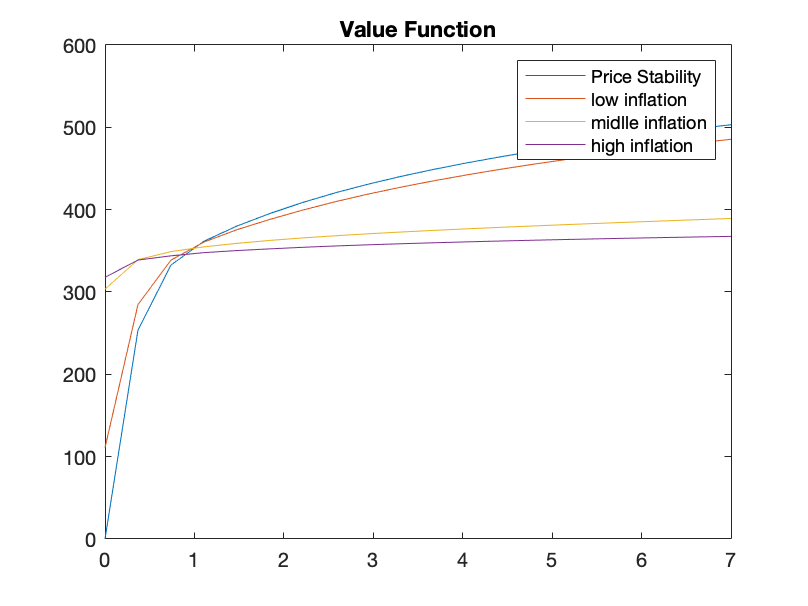

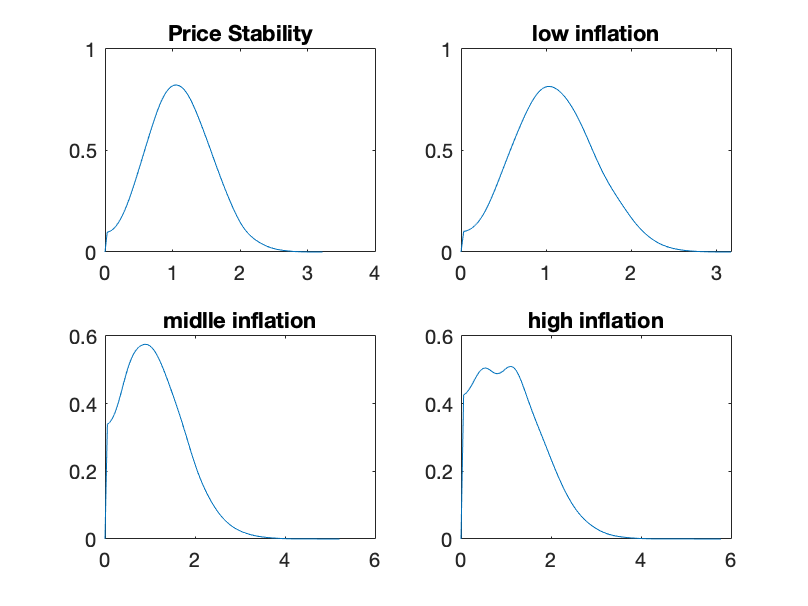

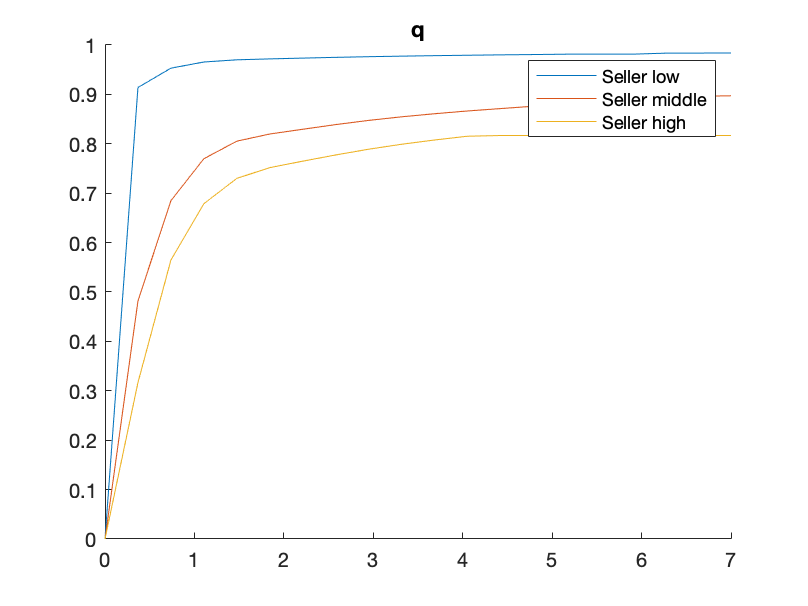

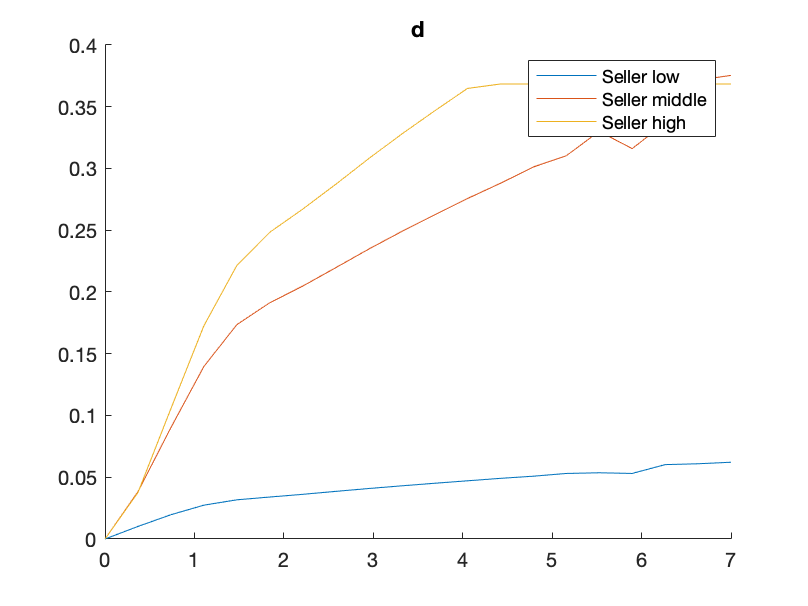

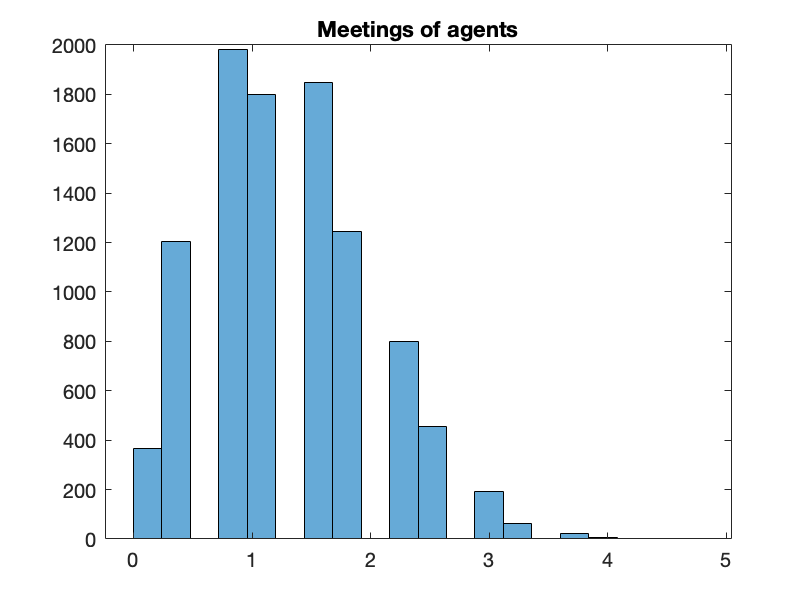

index = 1×25
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


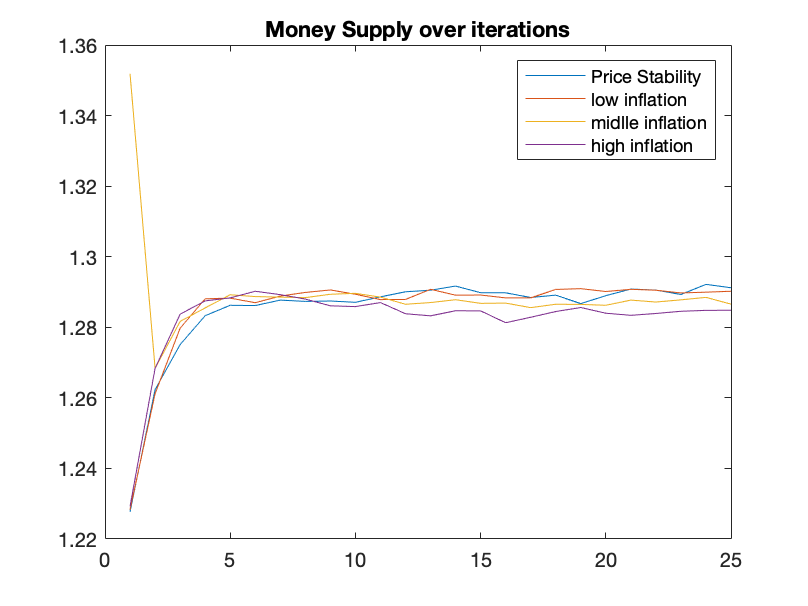

if display_plot_all==1

%Plot V
if display_plot_V==1
figure(1)
plot(m,V_all)
title('Value Function')
legend(mu_labels)

 end


%Plot Distribution Smooth
if display_plot_Distribution_smooth==1 
Distribution_all(Distribution_all==0)=0.001;
    figure(2)
    hold on
for l=1:n_calibration
[f(:,l),xi(:,l)] = ksdensity(Distribution_all(:,l),'Support','positive','BoundaryCorrection'...
    ,'reflection','Bandwidth',std(Distribution_all(:,l))*smoothing_parameter); 
    subplot(2,2,l)
plot(xi(:,l),f(:,l))
title(mu_labels(1,l))
 end
end

hold off

%Plot Distribution Rough
if display_plot_Distribution_rough==1
figure(3)
histogram(Distribution_all,grids*2)
 title('Distribution of Money holdings')
 legend(mu_labels)
 end




%Plot q (first iteration)
 if display_plot_q==1
figure(4)
hold on
plot(m,q_all(:,1,1))
plot(m,q_all(:,round(grids/2),1))
plot(m,q_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('q')

 end




%Plot d (last iteration)
 if display_plot_d==1
figure(5)
hold on
plot(m,d_all(:,1,1))
plot(m,d_all(:,round(grids/2),1))
plot(m,d_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('d')
 end

%Plot cdf
if display_plot_cdf==1
figure (6)
plot(m,cdf)
title('cdf')
end


% Plot Money Savings
if display_plot_money_savings==1
m_savings_1=m'-d(:,1);
m_savings_2=m'-d(:,round(grids/2));
m_savings_3=m'-d(:,grids-1);
figure(7)
hold on
plot(m',m_savings_1)
plot(m',m_savings_2)
plot(m',m_savings_3)
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('Money Savings')
end



% Plot Mettings
if display_plot_meeting==1
for i=1:N
Meeting(1,i)=m(1,Meeting(1,i));
end
figure (8)
histogram(Meeting,grids)
title('Meetings of agents')
end



%Plot M_track_1
if display_plot_M_Track_1==1
index=[1:iterations]
figure(9)
plot(index, M_track_1)
title('Money Supply over iterations')
legend(mu_labels)
end

end

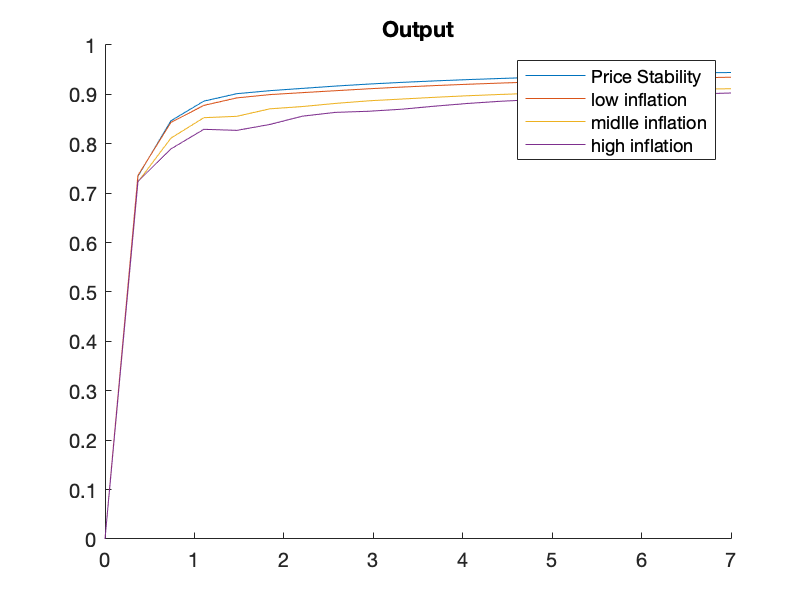


% Plot all q

 if display_plot_q_all==1
figure(10)
hold on
plot(m,q_all(:,3,1))
plot(m,q_all(:,3,2))
plot(m,q_all(:,3,3))
plot(m,q_all(:,3,4))
legend(mu_labels)
hold off
title('Output')
 end

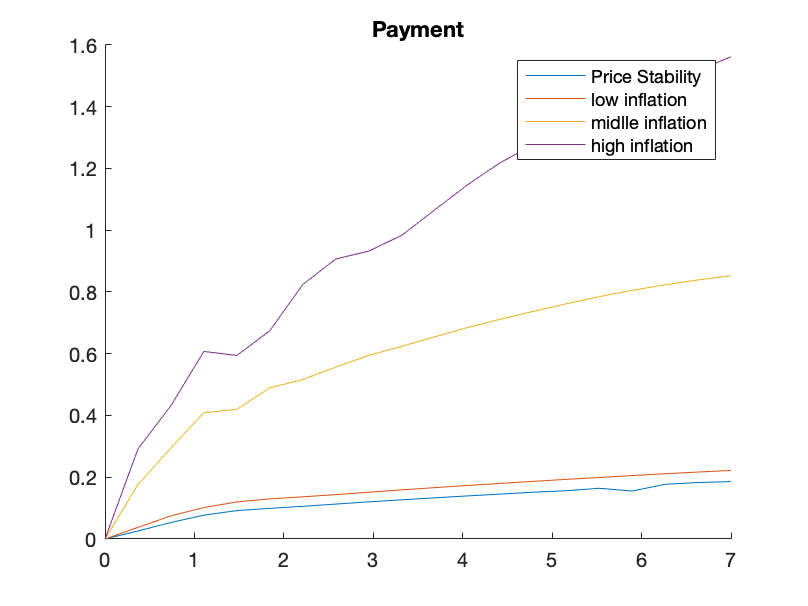


% Plot all d


  if display_plot_d_all==1
figure(11)
hold on
plot(m,d_all(:,3,1))
plot(m,d_all(:,3,2))
plot(m,d_all(:,3,3))
plot(m,d_all(:,3,4))
legend(mu_labels)
hold off
title('Payment')
 end






toc

Elapsed time is 386.718944 seconds.


## Tables

data_table=[average_q;average_price;std_distribution;velocity; average_real_balances]'

data_table = 4×5
    0.8389    0.1250    0.4571    0.0812   10.3280
    0.8397    0.1557    0.4634    0.1013    8.2862
    0.7905    0.5276    0.6539    0.3242    2.4385
    0.7522    0.8456    0.7022    0.4951    1.5194


figure(20)
 t=uitable(figure,'Data', data_table, 'Position', [100 100 500 200])

t =   Table with properties:

                Data: [4×5 double]
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [100 100 500 200]
               Units: 'pixels'

  Show all properties


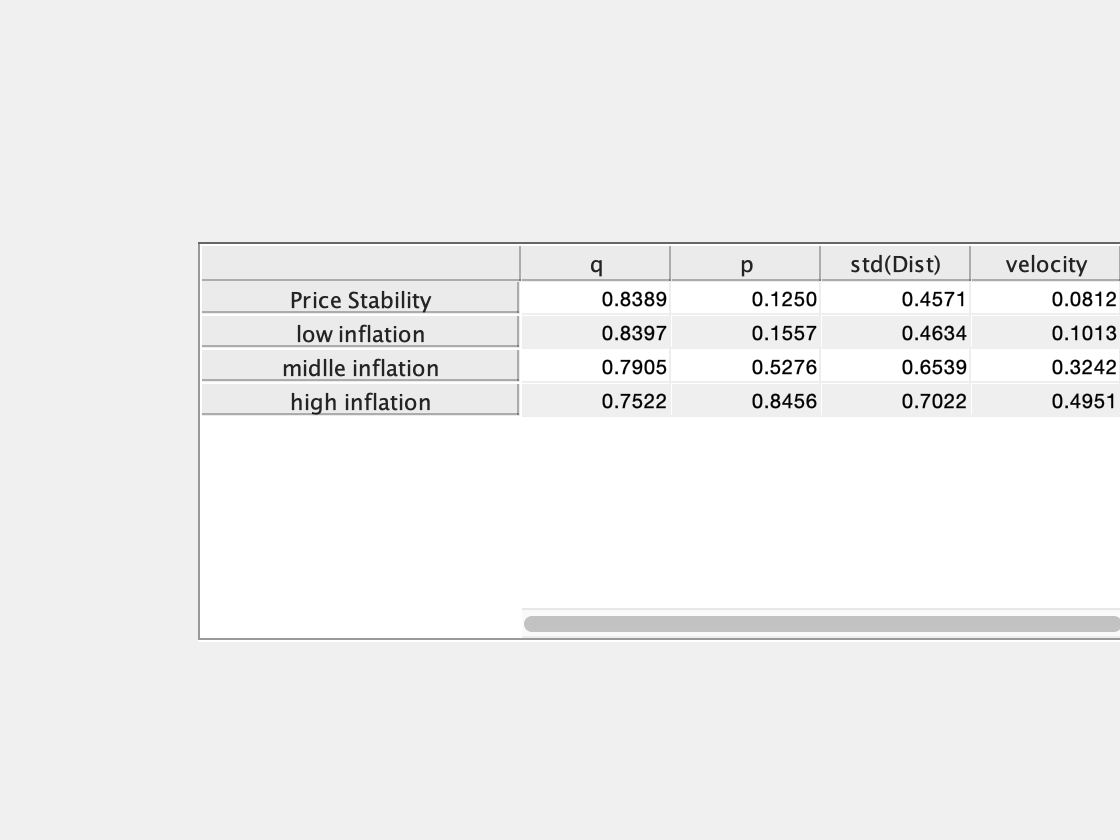

set(t, 'columnname', {'q', 'p','std(Dist)','velocity', 'real balances'})
set(t, 'rowname', mu_labels)